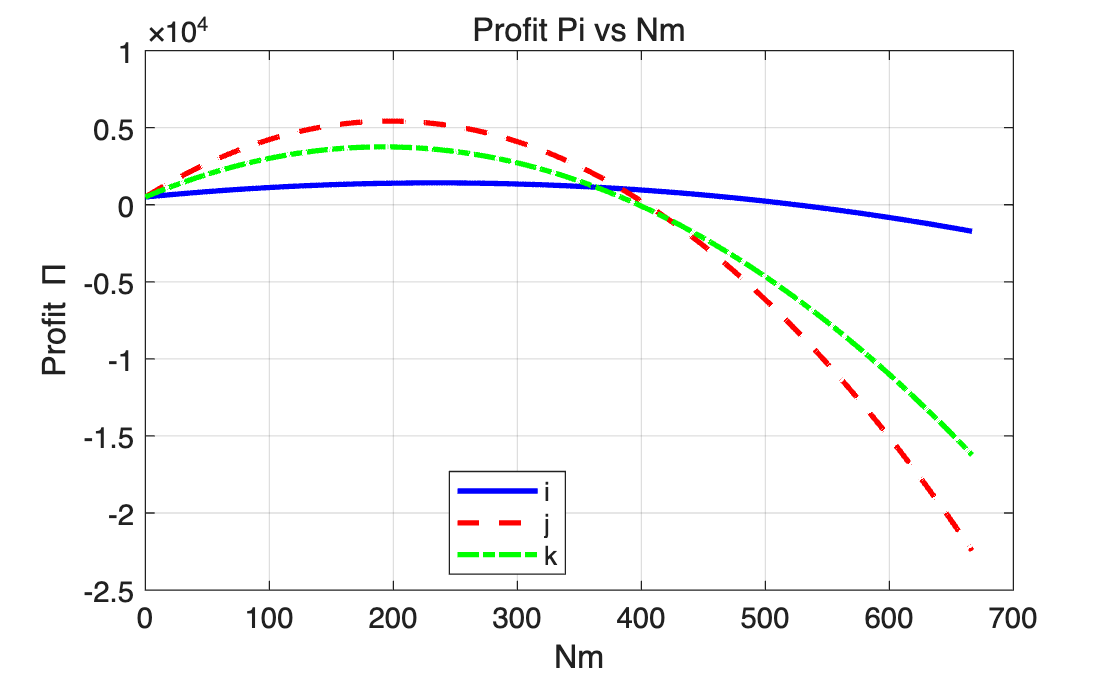

%{
clear; clc; close all;

% 数据实验
D = 4000; % 需求规模
s = 2000;

alpha1 = 6.4;         
beta = 0.61*alpha1;
gamma = 2.38*alpha1;
alpha2 = 0.7*alpha1;

n = 6;
Cb = 20;
Cab = Cb/n; % 平均公交成本
Ct = beta*gamma/(beta+gamma)*D/s;        % 全私家车通勤成本

lambda = 4;        % 模块化公交效率参数
R_Nm_star = 500;      % 固定收益（R(N_m^*)）



% 混合车道
p_i = beta*gamma/(beta+gamma)*(alpha1-alpha2)/(alpha1*s)*(D-n*Nm)

Pi_i = n .*Nm .*p_i + R_Nm_star - Nm .*Cab
CS_i = (lambda-1)/(2*lambda)*Ct*n .*Nm
SW_i = CS_i + Pi_i


% 专用车道
p_j = beta*gamma/(beta+gamma)/((1-theta)*s)*(D-(1-theta+theta*lambda)/(theta*lambda)*n*Nm)

Pi_j = n .*Nm .*p_j + R_Nm_star - Nm .*Cab
CS_j = 1/2*1 ./(1-theta)*Ct*n .*Nm
SW_j = CS_j + Pi_j


% 间歇性专用车道
p_k = beta*gamma/(beta+gamma)*1/s*(D-(1-theta+theta*lambda)/(theta*lambda)*n*Nm)

Pi_k = n .* Nm .* p + R_Nm_star - Nm .* Cab
CS_k = 0.5 * (lambda-1) ./lambda .* Ct .* n .* Nm
SW_k = CS_k + Pi_k

%}


clear; clc; close all;

%% 参数设定
D = 4000; 
s = 2000;

alpha1 = 6.4;         
beta = 0.61*alpha1;
gamma = 2.38*alpha1;
alpha2 = 0.7*alpha1;

n = 6;
Cb = 20;
Cab = Cb/n;
Ct = beta*gamma/(beta+gamma)*D/s;

lambda = 4;
theta = 0.3;
R_Nm_star = 500;

%% 自变量 Nm
Nm = linspace(0, D/n, 500);  % Nm 变化范围

%% 价格计算
p_i = beta*gamma/(beta+gamma)*(alpha1-alpha2)/(alpha1*s).*(D-n*Nm);
p_j = beta*gamma/(beta+gamma)./((1-theta)*s).*(D-(1-theta+theta*lambda)/(theta*lambda)*n.*Nm);
p_k = beta*gamma/(beta+gamma)/s.*(D-(1-theta+theta*lambda)/(theta*lambda)*n.*Nm);

%% 利润 Pi
Pi_i = n .* Nm .* p_i + R_Nm_star - Nm .* Cab;
Pi_j = n .* Nm .* p_j + R_Nm_star - Nm .* Cab;
Pi_k = n .* Nm .* p_k + R_Nm_star - Nm .* Cab;

%% 消费者剩余 CS
CS_i = 0.5*  (lambda-1)/lambda * Ct * n .* Nm;
CS_j = 0.5/(1-theta) * Ct * n .* Nm;
CS_k = 0.5 * (lambda-1)/lambda * Ct * n .* Nm;  

%% 社会福利 SW
SW_i = Pi_i + CS_i;
SW_j = Pi_j + CS_j;
SW_k = Pi_k + CS_k;

%% 绘图 - Pi-Nm
figure;
plot(Nm, Pi_i, 'b-', 'LineWidth', 2); hold on;
plot(Nm, Pi_j, 'r--', 'LineWidth', 2);
plot(Nm, Pi_k, 'g-.', 'LineWidth', 2);
xlabel('Nm'); ylabel('Profit \Pi');
title('Profit Pi vs Nm');
legend({'i','j','k'}, 'Location','best');
grid on; box on;

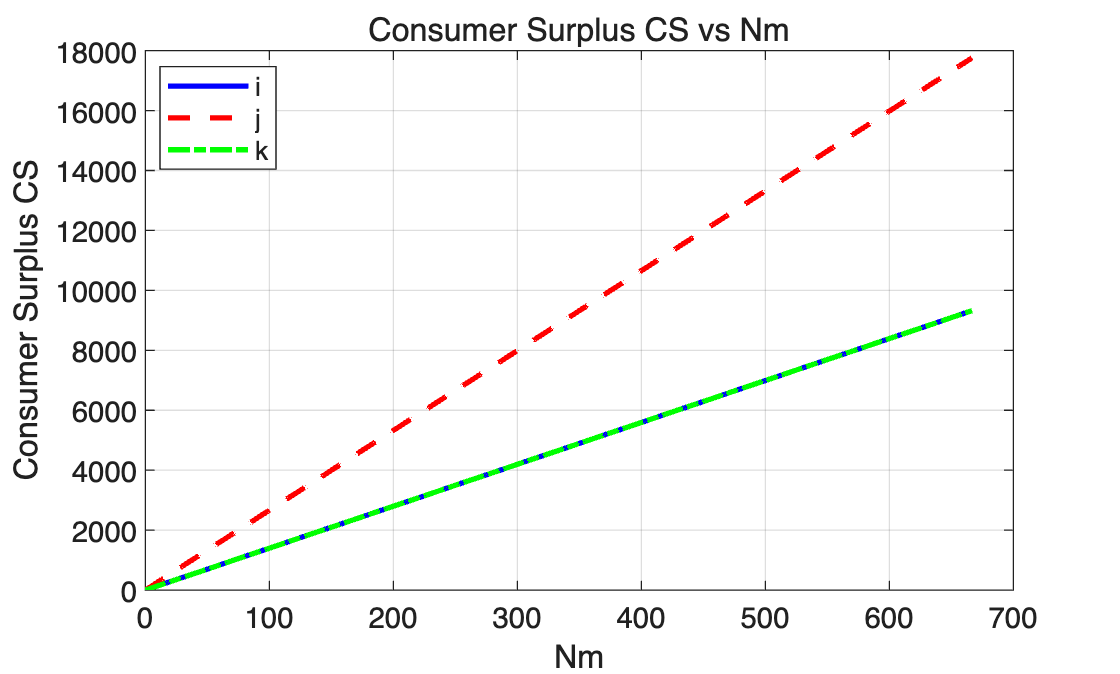


%% 绘图 - CS-Nm
figure;
plot(Nm, CS_i, 'b-', 'LineWidth', 2); hold on;
plot(Nm, CS_j, 'r--', 'LineWidth', 2);
plot(Nm, CS_k, 'g-.', 'LineWidth', 2);
xlabel('Nm'); ylabel('Consumer Surplus CS');
title('Consumer Surplus CS vs Nm');
legend({'i','j','k'}, 'Location','best');
grid on; box on;

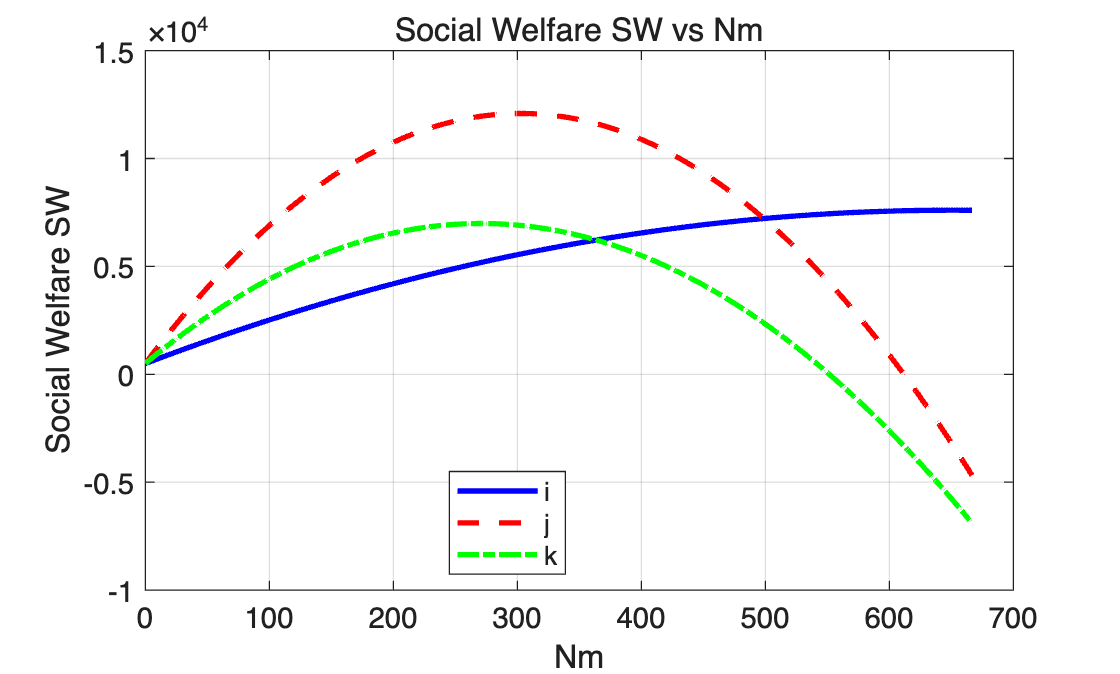


%% 绘图 - SW-Nm
figure;
plot(Nm, SW_i, 'b-', 'LineWidth', 2); hold on;
plot(Nm, SW_j, 'r--', 'LineWidth', 2);
plot(Nm, SW_k, 'g-.', 'LineWidth', 2);
xlabel('Nm'); ylabel('Social Welfare SW');
title('Social Welfare SW vs Nm');
legend({'i','j','k'}, 'Location','best');
grid on; box on;

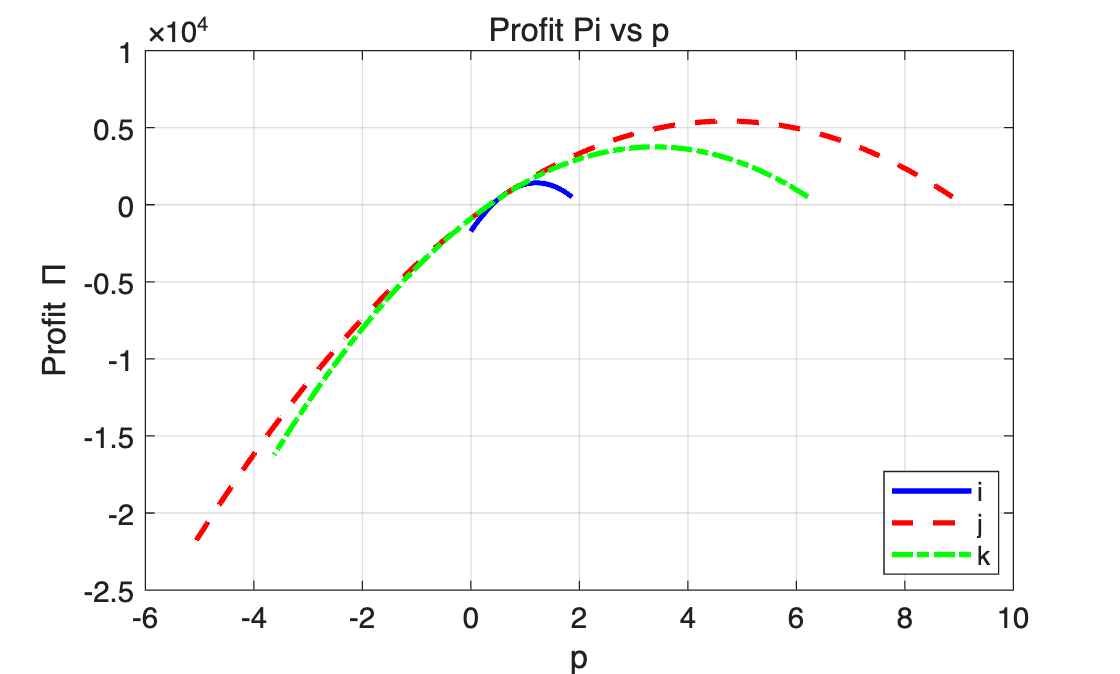



%% 绘图 - Pi-p
figure;
plot(p_i, Pi_i, 'b-', 'LineWidth', 2); hold on;
plot(p_j, Pi_j, 'r--', 'LineWidth', 2);
plot(p_k, Pi_k, 'g-.', 'LineWidth', 2);
xlabel('p'); ylabel('Profit \Pi');
title('Profit Pi vs p');
legend({'i','j','k'}, 'Location','best');
grid on; box on;

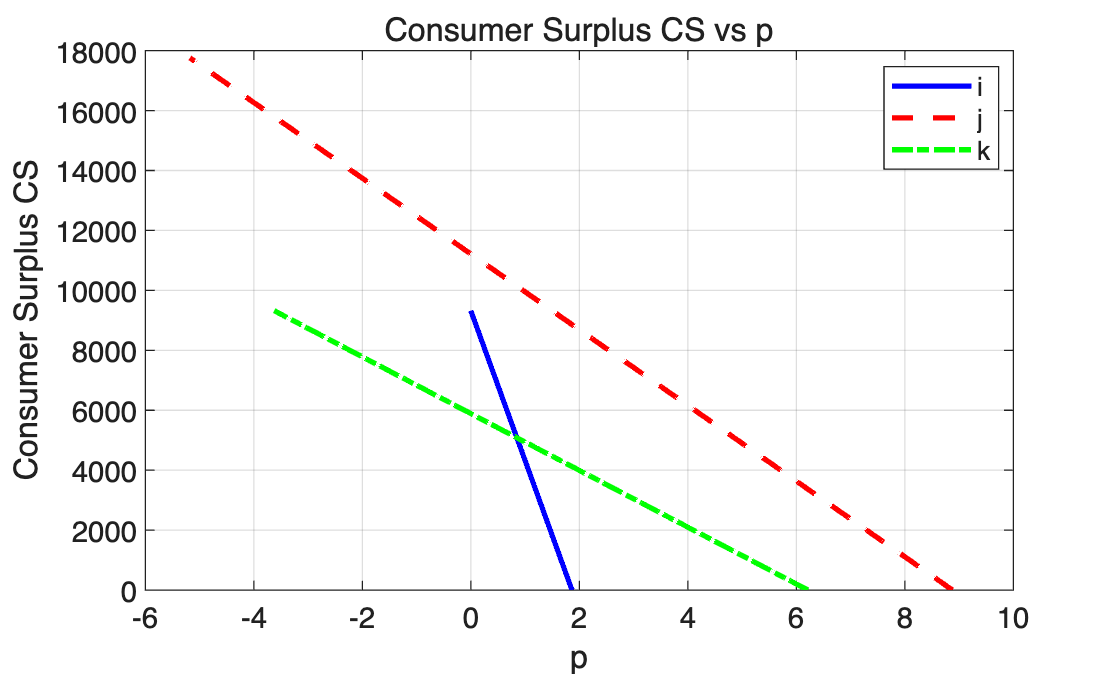


%% 绘图 - CS
figure;
plot(p_i, CS_i, 'b-', 'LineWidth', 2); hold on;
plot(p_j, CS_j, 'r--', 'LineWidth', 2);
plot(p_k, CS_k, 'g-.', 'LineWidth', 2);
xlabel('p'); ylabel('Consumer Surplus CS');
title('Consumer Surplus CS vs p');
legend({'i','j','k'}, 'Location','best');
grid on; box on;

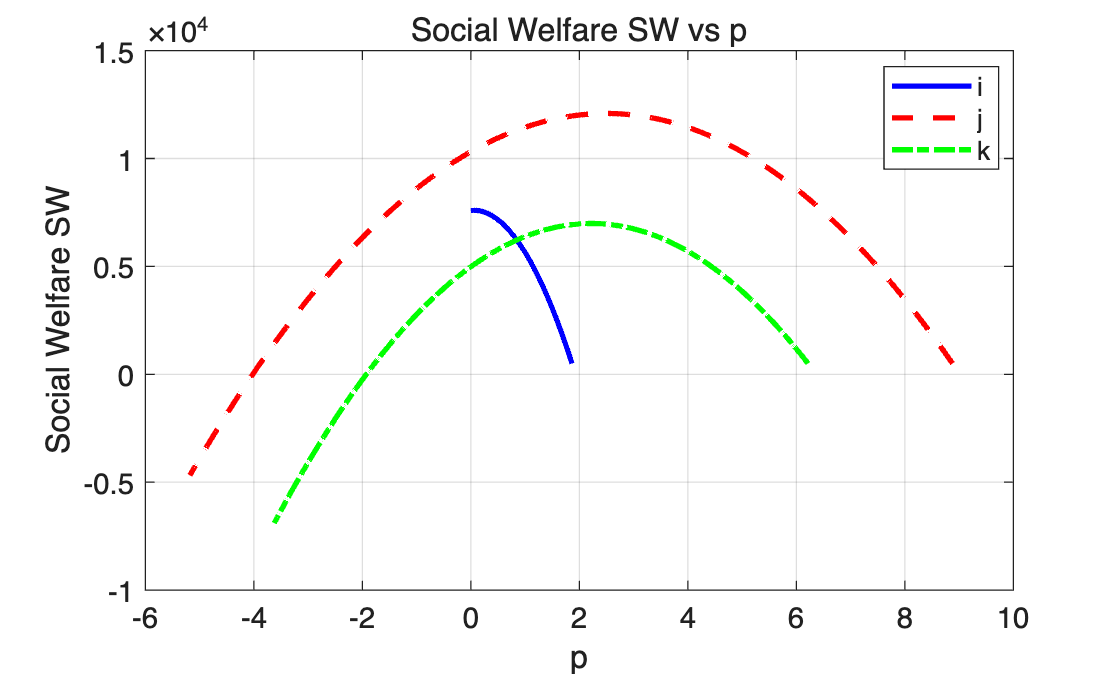


%% 绘图 - SW
figure;
plot(p_i, SW_i, 'b-', 'LineWidth', 2); hold on;
plot(p_j, SW_j, 'r--', 'LineWidth', 2);
plot(p_k, SW_k, 'g-.', 'LineWidth', 2);
xlabel('p'); ylabel('Social Welfare SW');
title('Social Welfare SW vs p');
legend({'i','j','k'}, 'Location','best');
grid on; box on;